# 4D primary mixed-mode SSM for the dynamic buckling of a beam

In this example, we apply a sufficiently large longitudinal compression force to a pinned-pinned von Kármán beam [1] and seek to derive an SSM-reduced nonlinear model for the ensuing buckling dynamics [2].

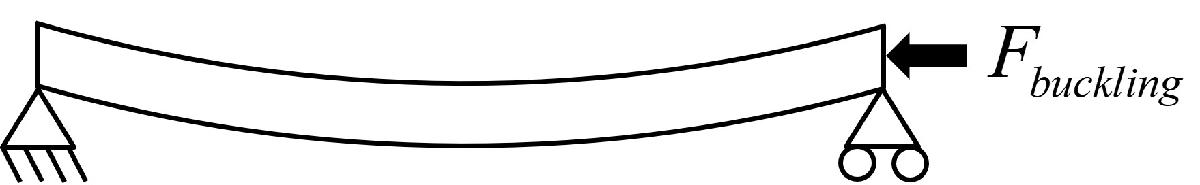

[1] S. Jain, P. Tiso, and G. Haller, Exact nonlinear model reduction for a von Kármán beam: slow-fast decomposition and spectral submanifolds, *Journal of Sound and Vibration* 423 (2018) 195-211. [https://doi.org/10.1016/j.jsv.2018.01.049](https://doi.org/10.1016/j.jsv.2018.01.049)

[2] G. Haller, B. Kaszás, A. Liu and J.Axås, Data-Driven Nonlinear Model Reduction to Fractional and Mixed-Mode Spectral Submanifolds, to be submitted.

clearvars
close all
addpath tools

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


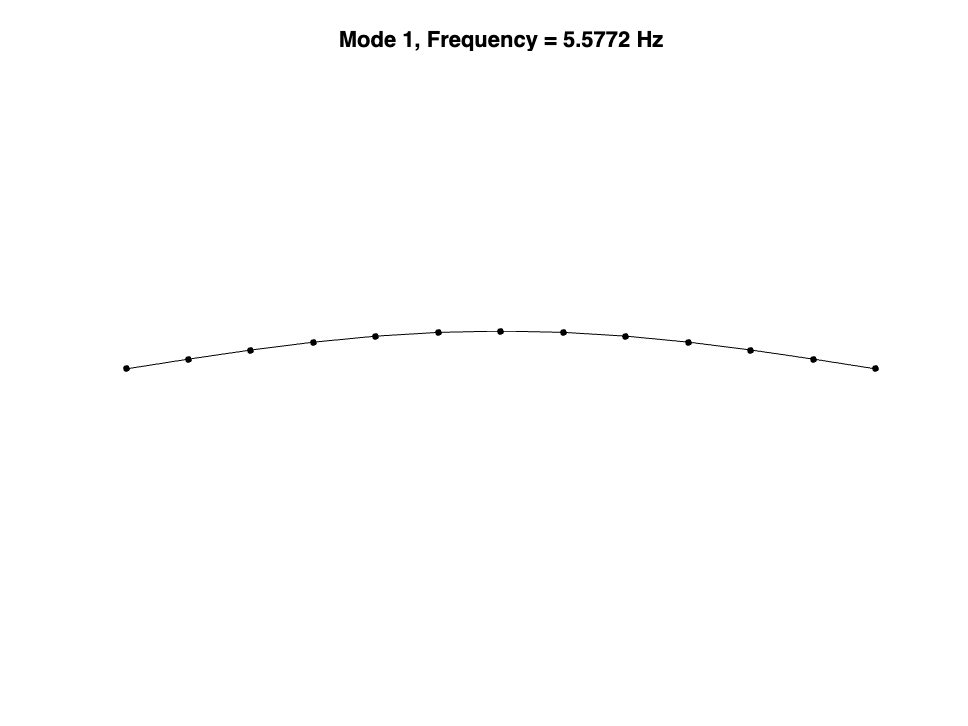

Assembling external force vector
Getting nonlinearity coefficients
Assembling Tensors
Total time spent on model assembly = 00:00:00


nElements = 12;
l = 2; h = 1e-2; b = 5e-2; % Mesh parameters
E = 190e9;  % Young's modulus
[M, C, K, fnl, fExt, obsdof, PlotFieldonDefMesh] = buildModelBuckling(nElements,l,h,b,E);

n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)

We apply buckling force larger than Euler's critical load


$$F = \frac{N^2 \pi ^2 EI}{L^2} = \frac{\pi ^2 Ebh^3}{12 L^2}$$


loads = [1.1]*pi^2* E * b*(h)^3 /12 / l^2;  
loadvector = loads.*fExt;
[F_0, ~] = functionFromTensors(M, C, K, fnl);
unstable_fp = getStaticResponseIC(K, M, F_0, -loadvector, 0, PlotFieldonDefMesh); 

## Training data generation

We divide the data into a training set containing four trajectories, and a test set containing two trajectories for validation. 

nTraj = 9; % number of training trajectories
indTest = 9;
indTrain = 1:8;

Since in SSMLearn, the SSM is attached to the fixed point at the origin, we move the origin to the unstable steady state under the buckling force, and compute the corresponding eigenvalues. To save execution time and avoid rerunning the system differentiation, `newSystem` can be set to `false`.

newSystem = false;
if newSystem
    [~, lambda, V] = functionFromTensorsFP(M, C, K, fnl, loadvector, unstable_fp);
else
    load vonkarmandata/A_t.mat
    [~, lambda, V] = functionFromTensorsFP(M, C, K, fnl, loadvector, unstable_fp, A_t);
end
lambda_10 = sort(lambda); 
disp('first 10 eigenvalues of the system:'); disp( lambda_10(1:10) );

first 10 eigenvalues of the system:
   1.0e+02 *

   0.1106 + 0.0000i
  -0.1110 + 0.0000i
  -0.0036 - 1.1936i
  -0.0036 + 1.1936i
  -0.0183 - 2.9556i
  -0.0183 + 2.9556i
  -0.0580 - 5.4150i
  -0.0580 + 5.4150i
  -0.1419 - 8.5819i
  -0.1419 + 8.5819i



[F, ~] = functionFromTensors(M, C, K, fnl, loadvector, 0);
[~,inx] = mink(lambda,4); % tangent space of 4D SSM at origin
tangentSpace = [ real( V(:,inx(1:2)) ), real(V(:,inx(3))), imag(V(:,inx(3)))];

We then apply static force to get initial conditions. The initial conditions of the first mode training trajectories can either be generated by applying a small perturbation to the unstable fixed point, or by applying a large transverse force at middle node, as the same in 2D buckling example. 

IC = zeros(2*n,nTraj);
loadvector_IC1 = zeros(size(loadvector));
loadvector_IC1(18) = 1; % transverse direction of midpoint, dof 18
loadAmp = [1e-4 -1e-4 6e3 -6e3 1e3 -1e3]; % amplitude of static forces
for i = 1 : 4 % calculate initial conditions
    IC(:,i) = getStaticResponseIC(K, M, F_0, loadvector_IC1*loadAmp(i), 0, PlotFieldonDefMesh);
end

To include training data of second mode, the initial condition can be set either as the second buckling mode itself (when applied a second mode force), or the static response of two symmetric transverse forces to the quarter-points.

loadvector_IC2 = zeros(size(loadvector));
loadvector_IC2(9) = 1; loadvector_IC2(27) = -1;
for i = 5 : 6 % calculate initial conditions
    IC(:,i) = getStaticResponseIC(K, M, F_0, loadvector_IC2*loadAmp(i), 0, PlotFieldonDefMesh);
end
load_mode2 = zeros(size(loadvector)); load_mode2(35) = -loads*2^2*1.1;
load_sin = zeros(size(loadvector)); load_sin(9) = 1e3; load_sin(27) = -1e3;
sin = getStaticResponseIC(K, M, F_0, load_sin, 0, PlotFieldonDefMesh);
IC(:,7) = getStaticResponseIC(K, M, F_0, load_mode2, 0, PlotFieldonDefMesh,sin(1:36));
load_sin = - load_sin; sin = getStaticResponseIC(K, M, F_0, load_sin, 0, PlotFieldonDefMesh);
IC(:,8) = getStaticResponseIC(K, M, F_0, load_mode2, 0, PlotFieldonDefMesh,sin(1:36));

The initial condition of the testing data is generated by applying a different second mode buckling force.

load_mode2(35) = -loads*2^2*1; load_sin(9) = 0.7e3; load_sin(27) = -0.7e3;
sin = getStaticResponseIC(K, M, F_0, load_sin, 0, PlotFieldonDefMesh);
IC(:,9) = getStaticResponseIC(K, M, F_0, load_mode2, 0, PlotFieldonDefMesh,sin(1:36));

Then the trajectories are integrated. Simulation time is about 5 mins each trajectory. To save execution time and avoid rerunning the simulation, `newMeasurement` can be set to `false`.

newMeasurement = false;
observable = @(x) x;
slowTimeScale = 2*pi/abs(lambda(1));
if newMeasurement
    numberPeriods = 150; 
    numberPointsPerPeriod = 100; 
    endTime = numberPeriods*slowTimeScale;
    nSamp = numberPeriods*numberPointsPerPeriod+1;
    dt = endTime/(nSamp-1);
    xData = integrateTrajectories(F, endTime, IC , nSamp, observable, 'odesolver', @ode45);
    DataInfo = struct('nElements', nElements, 'loadvector', loadvector);
    save('vonkarmandata/dataVKDecay_mode2.mat', 'DataInfo', 'xData', 'dt', 'endTime', 'nSamp', 'lambda')
else
    load vonkarmandata/dataVKDecay_mode2.mat
    if nElements ~= DataInfo.nElements
       error('The loaded data comes from a model with a different number of elements.')
    end
end

## Data analysis

We need to make sure that the data that we use to identify the mixed-mode SSM lies close to it. We keep only the time interval `sliceInt`.

sliceInt = [5*slowTimeScale, endTime]; xData(1:4,:) = sliceTrajectories(xData(1:4,:), sliceInt);
sliceInt = [10*slowTimeScale, endTime]; xData(5:8,:) = sliceTrajectories(xData(5:8,:), sliceInt);
sliceInt = [20*slowTimeScale, endTime]; xData(9,:) = sliceTrajectories(xData(8,:), sliceInt);

We observe three DoFs: transverse displacement and velocity of midpoint, and axial displacement of right endpoint. The red and blue trajectories lie on the first mode 2D saddle manifold, purple and yellow ones are the second mode data, oscillating and intersecting the saddle plane.

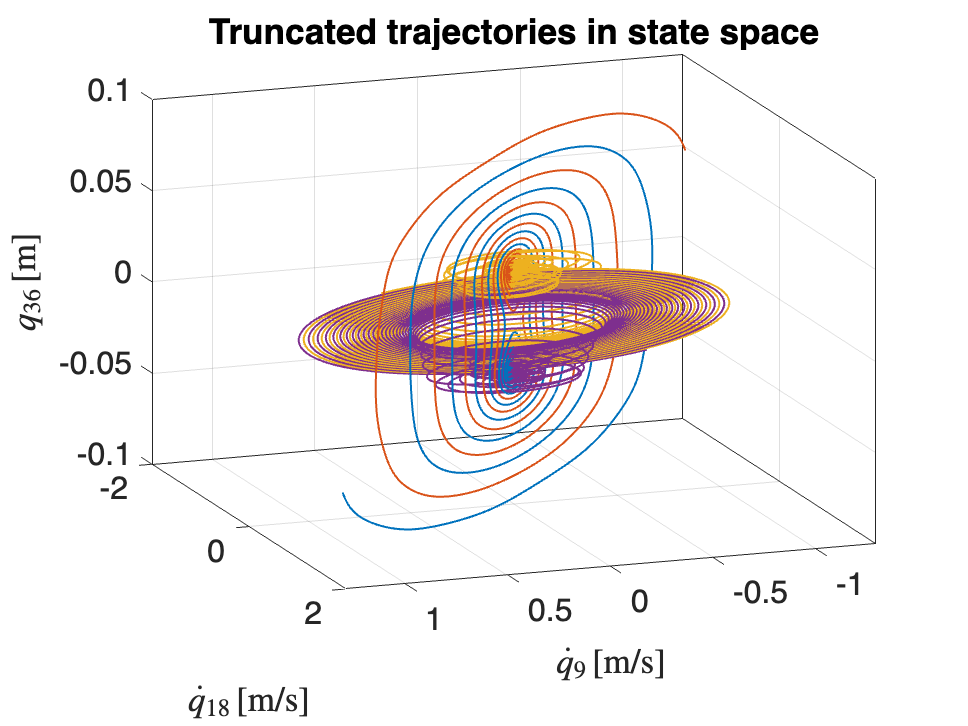

customFigure(); 
for iTraj = [3 4 5 6] 
    plot3(xData{iTraj,2}(45,:), xData{iTraj,2}(54,:), xData{iTraj,2}(36,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlabel('$\dot{q}_{9} \, [$m/s$]$','Interpreter','latex'); 
ylabel('$\dot{q}_{18} \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$q_{36} \, [$m$]$'],'Interpreter','latex'); 
title('Truncated trajectories in state space')
view(-200,20)

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the first pair of real eigenvalues, and containing the two stable fixed points.

We seek the $2n\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y)$,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem is formulated as the minimization of a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top 
y_k) ||$$


to find $H$ and the $2n\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab routine `fmincon` in `IMGeometry`. To make the process more accurate, an alternative can be provided if linear part of dynamics of the system are known and used for dynamics fitting. For illustration purpose, we set this as input to the code.

To fasten the computation, here we set the SSM to order three. Change to order seven to have more accurate results that corresponds to the paper.

SSMDim = 4; SSMOrder = 3; % 7
[IMInfo, SSMChart, SSMFunction] = IMGeometry(xData(indTrain,:), SSMDim, SSMOrder,'V_e',tangentSpace);

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace $\eta = V_e^\top y$. We plot the trajectories in reduced coordinates:

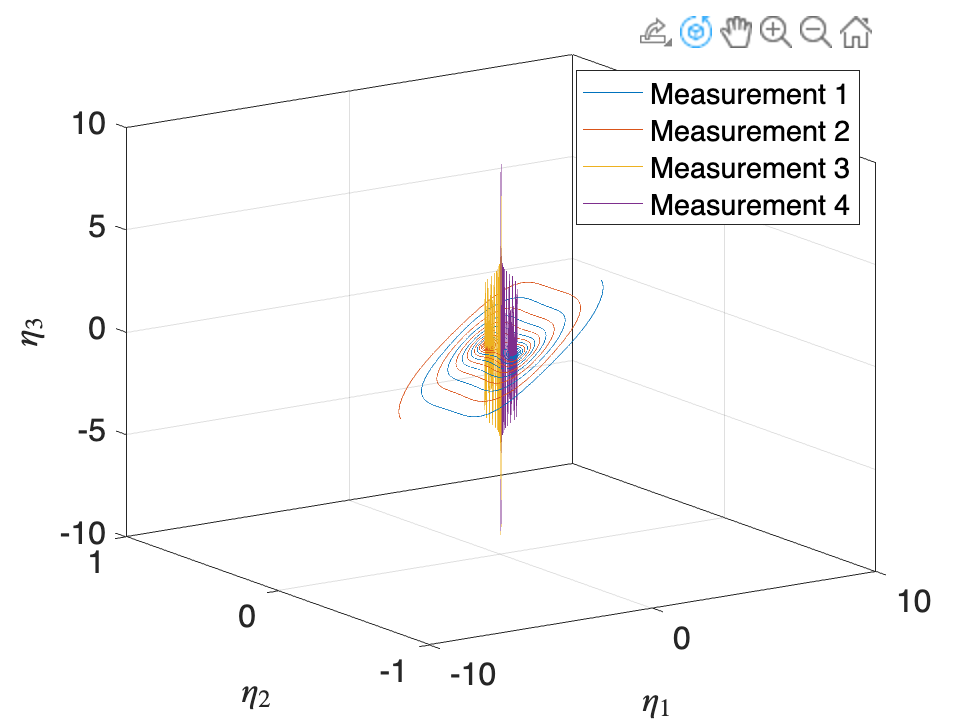

etaData = projectTrajectories(IMInfo, xData);
plotReducedCoordinates(etaData(3:6,:),'plotinds',[1 2 3]); view(3)

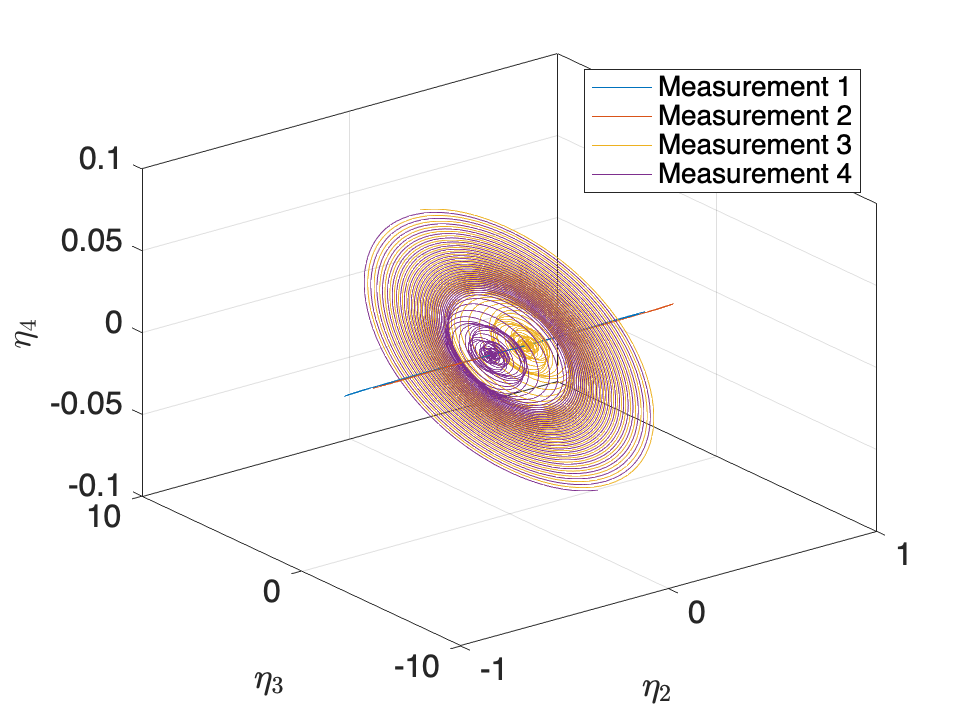

plotReducedCoordinates(etaData(3:6,:),'plotinds',[2 3 4]); view(3)

Since the SSM in this case is four dimensional and cannot be visualized, only truncated trajectories are shown.

We compute the manifold fitting error:

xxData = transformTrajectories(IMInfo.parametrization.map, etaData);
normedTrajDist = computeTrajectoryErrors(xxData, xData);
Error = mean(normedTrajDist(indTest));
disp('Manifold fitting error:'); disp( Error );

Manifold fitting error:
   3.1803e-04



## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map


$$\dot{\eta} = R(\eta) = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and  $W_r$ is a matrix of polynomial coefficients. 

ROMOrder = 7; 
RDInfo = IMDynamicsFlow(etaData(indTrain,:),'R_PolyOrd', ROMOrder, 'style', 'modal');

Estimation of the reduced dynamics...  Done. 


We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory. The imaginary parts are ignored.

[xRec, etaRec, zRec] = advect(IMInfo, RDInfo, xData );
for i = 1:nTraj
    xRec{i,2} = real( xRec{i,2} ); zRec{i,2} = real( zRec{i,2} ); etaRec{i,2} = real( etaRec{i,2} );
end

If we know $D$ from the model, we can enforce it in the data-driven dynamics identification. To do so, we fix the linear part of $R$. These dynamics act on coordinates being orthogonal projections on the eigenspace, which are not modal coordinates where the linear part of the dynamics is indeed the diagonal matrix $D$. However, these two coordinate systems are linked by a linear transformation. More precisely, we define $P = V_e^\top E$ , where the columns of $E$ are the eigenvectors related to the SSM. 

P = transpose(IMInfo.parametrization.tangentSpaceAtOrigin)*tangentSpace;
zData = etaData; % modal coordinates
for i = 1:nTraj
    zData{i,2} = real( P\zData{i,2} );
end

## Evaluation of reduced dynamics

The normalized mean trajectory error NMTE is computed as the average distance of the predicted trajectory to the measured one in the observable space, normalized by the observable vector with maximum norm in the data. 

normedTrajDist = computeTrajectoryErrors( xRec(indTest,:), xData(indTest,:) );
NMTE = mean(normedTrajDist);
disp('normalized mean trajectory error NMTE:'); disp( Error );

normalized mean trajectory error NMTE:
   3.1803e-04



We compare the testing data and their predictions in reduced coordinates:

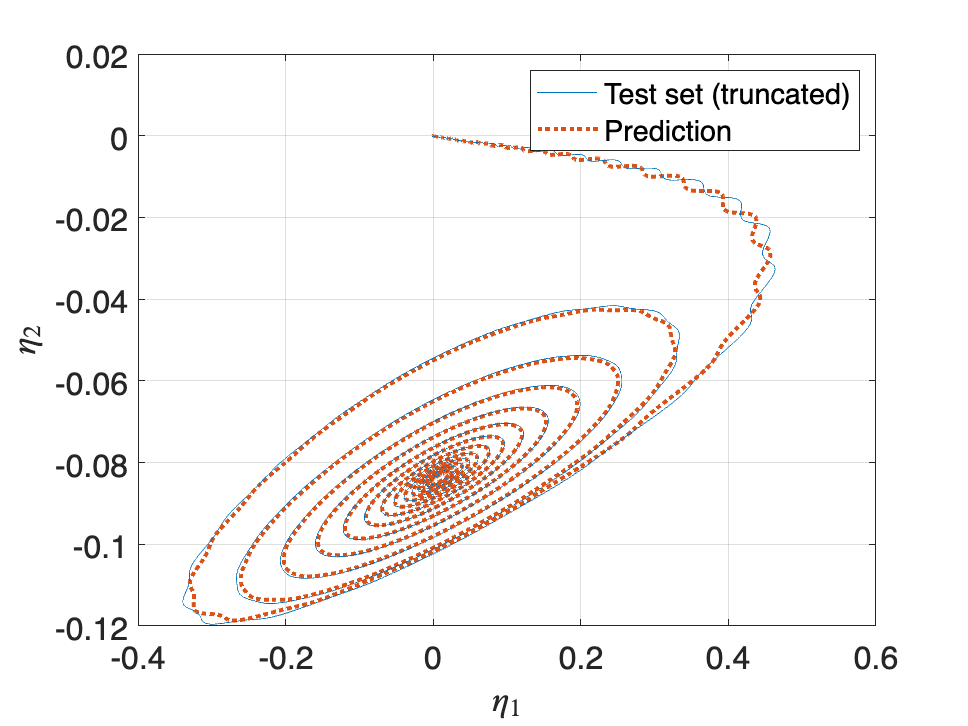

plotReducedCoordinates(etaData(indTest,:), etaRec(indTest,:),[1 2 3] )
legend({'Test set (truncated)', 'Prediction'})

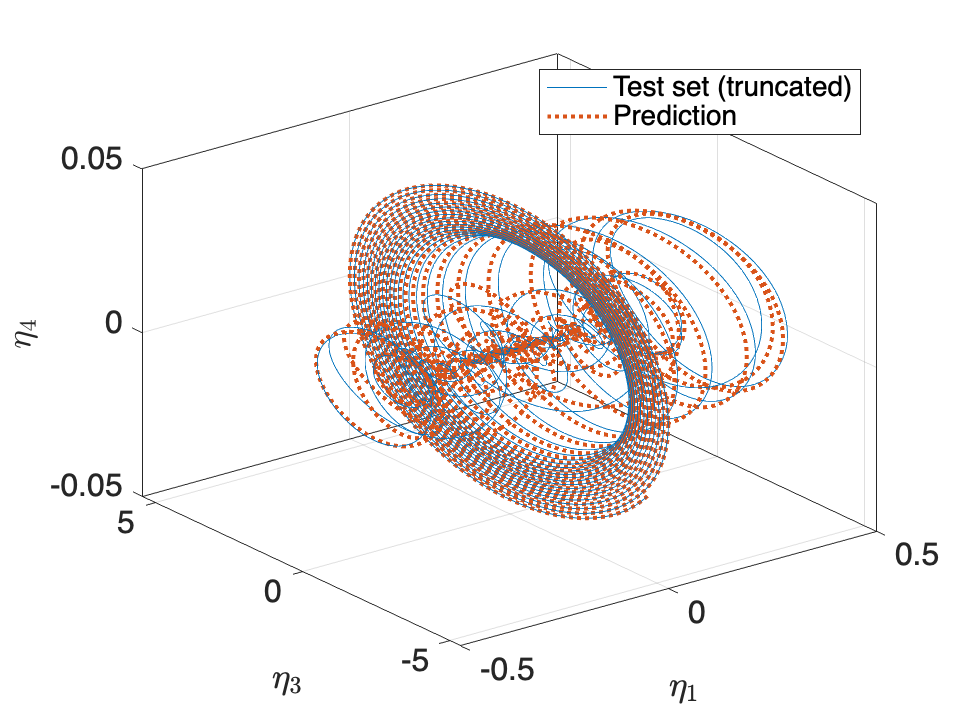

plotReducedCoordinates(etaData(indTest,:), etaRec(indTest,:),[1 3 4] )
legend({'Test set (truncated)', 'Prediction'}); view(3)

We plot the testing data and their predictions in model coordinates after the linear transformation:

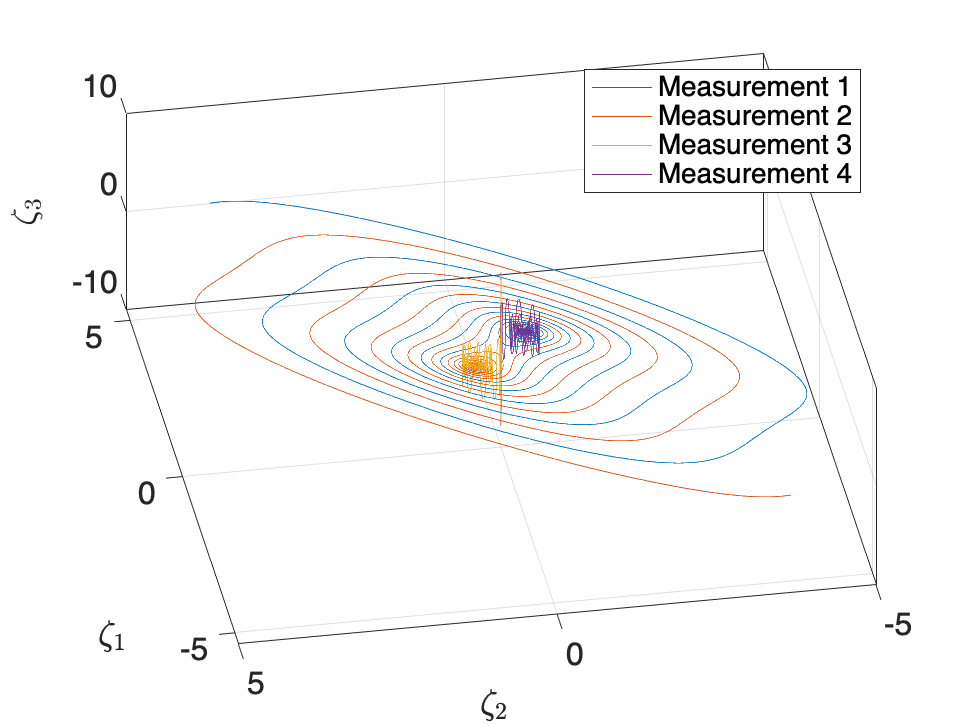

plotReducedCoordinates(zData([3 4 7 8],:),'plotinds',[1 2 3]); 
xlabel('$\zeta_1$','Interpreter','latex'); ylabel('$\zeta_2$','Interpreter','latex')
zlabel('$\zeta_3$','Interpreter','latex'); view(-100,60)

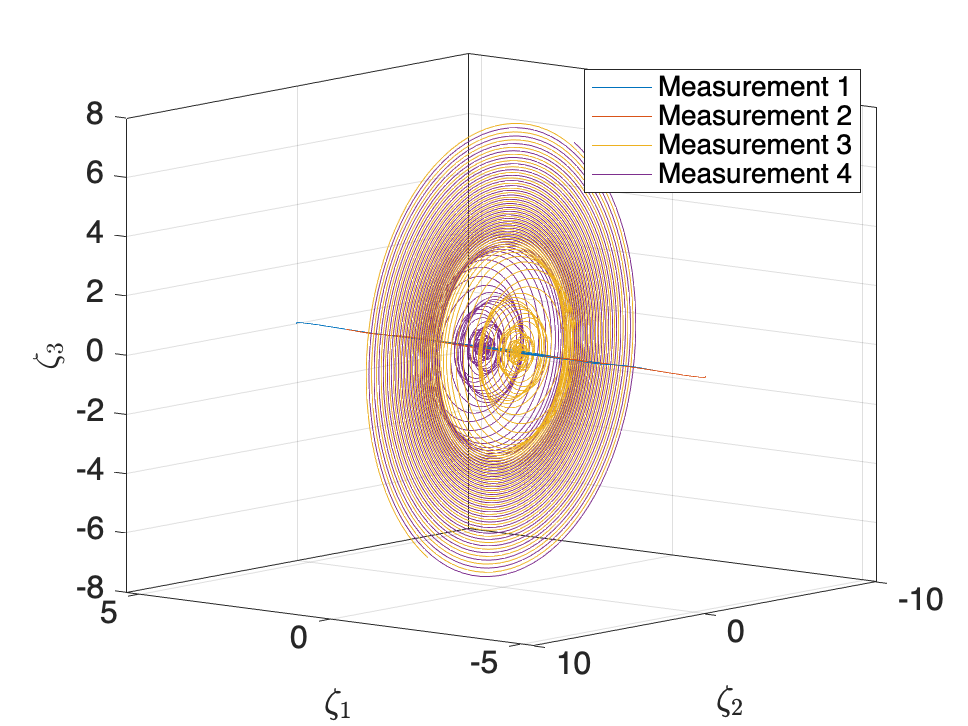

plotReducedCoordinates(zData([3 4 7 8],:),'plotinds',[1 3 4]); 
xlabel('$\zeta_1$','Interpreter','latex'); ylabel('$\zeta_2$','Interpreter','latex')
zlabel('$\zeta_3$','Interpreter','latex'); view(-140,10)

We also compare the testing data and their predictions in full state space:

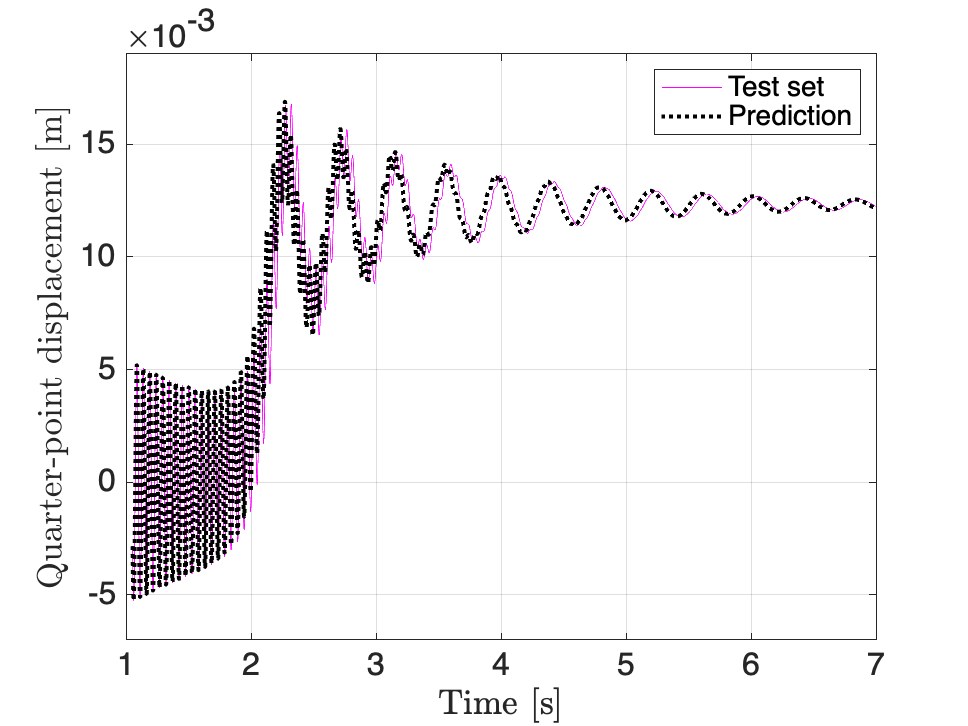

plotTrajectories(xData(indTest,:), xRec(indTest,:), 'm', 9, {'Test set', 'Prediction'}) 
ylabel('Quarter-point displacement $[$m$]$','Interpreter','latex')
xlabel('Time $[$s$]$','Interpreter','latex')
xlim([1 7]); ylim([-0.007 0.019]);

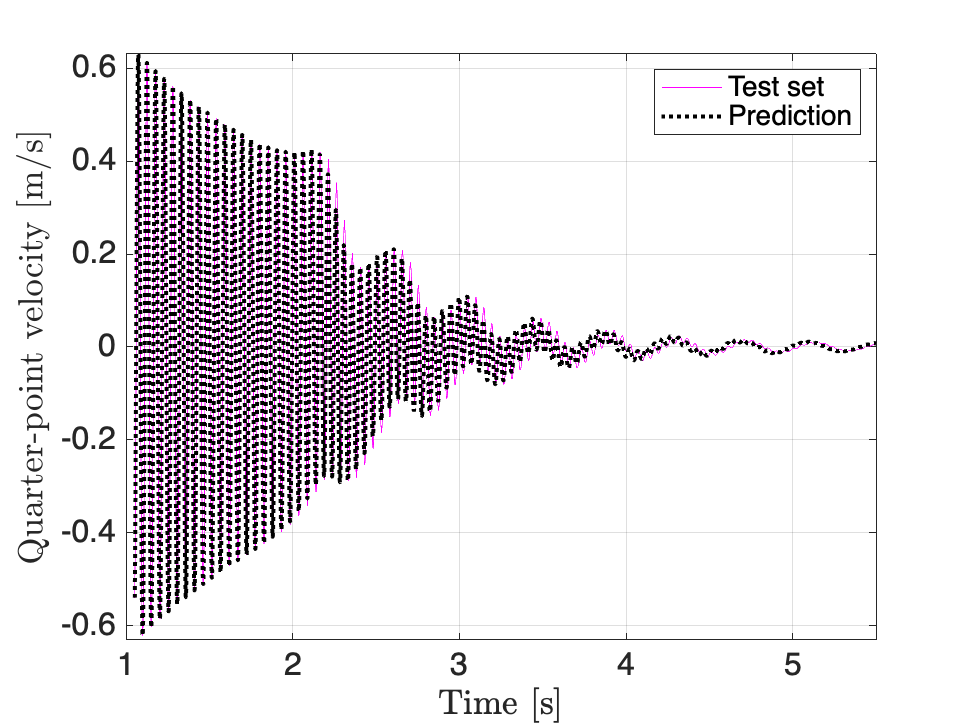


plotTrajectories(xData(indTest,:), xRec(indTest,:), 'm', 45, {'Test set', 'Prediction'}) 
ylabel('Quarter-point velocity $[$m/s$]$','Interpreter','latex')
xlabel('Time $[$s$]$','Interpreter','latex')
xlim([1 5.5]);